# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 3.4.3 Range Doppler Algorithm - Point Targets

## Calculate the range Doppler image

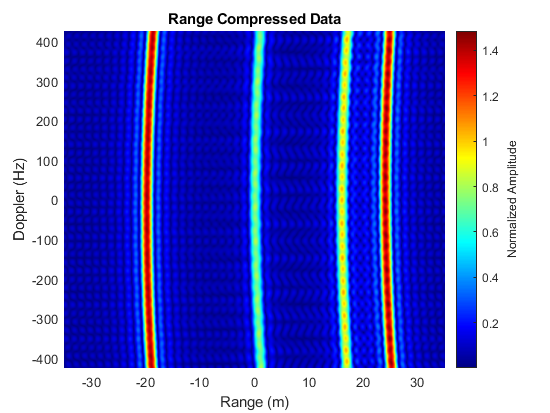

clear

c = 299792458;

% Load data
load('signal.mat')

% Find the number of signal samples
[nAz, nRange] = size(signal);

% Set the FFT sizes
nfft_Range = 8 * 2 ^ nextpow2(nRange);
nfft_Az = 2 ^ nextpow2(nAz);

% Calculate the slant range window
range_window_length = c / (2 * (frequency(2) - frequency(1)));
slant_range = linspace(-range_window_length/2, range_window_length/2, nfft_Range);
center_frequency = frequency(round(end/2));
wavelength = c / center_frequency;

% Set the window type for range compression
window = 'none';

% Get the window coefficients
switch window
    case 'Hanning'
        coefficients = hanning(nRange);
    case 'Hamming'
        coefficients = hamming(nRange);
    case 'Kaiser'
        coefficients = kaiser(nRange, 6);
    otherwise
        coefficients = ones(1, nRange);
end

% Perform range compression
Hf = exp(1j * 4.0 * pi .* frequency / c * range_center(round(end/2))) .* coefficients;
Sf = signal;
rd_data_corrected = zeros(nAz, nfft_Range);

% Loop over each range line
for i = 1:nAz    
    rd_data_corrected(i, :) = fftshift(ifft(Sf(i, :) .* Hf, nfft_Range));
end

% Set the PRF (Hz)
prf = 850;
frequency = linspace(-0.5 * prf, 0.5 * prf, nAz)';

% Plot the range compressed data
figure; pcolor(slant_range, frequency, abs(rd_data_corrected)); shading flat
xlabel('Range (m)');
ylabel('Doppler (Hz)');
title('Range Compressed Data');
h = colorbar;
ylabel(h, 'Normalized Amplitude')
colormap 'jet'

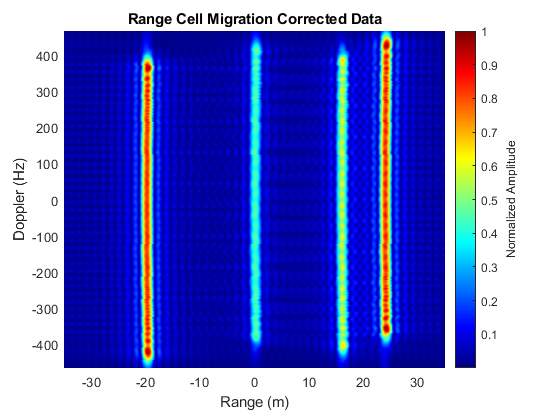


% Convert the range compressed data to range Doppler domain for 
% range cell migration correction
rd_data = fftshift(fft(rd_data_corrected),1);


% Calculate the slant range spacing
rc = range_center(round(end/2));
slant_range_spacing = slant_range(2) - slant_range(1);

% Effective velocity
v_eff = 100;

% Data size
[nA, nR] = size(rd_data);

% Frequency shift (Hz)
frequency = linspace(-0.5 * prf, 0.5 * prf, nA)';

% Calculate the RCMC offset
offset = (1./sqrt(1 - (wavelength * frequency / (2 * v_eff) ).^2) - 1) * rc;
offset = round(offset / slant_range_spacing);
frequency = frequency * 5;

% Index the RCMC data from the offset range doppler data
ind = reshape([1:nR  *nA], nA, nR) + offset * nA;
ind(ind>nR*nA) = (nR)*nA;
rcmc_data = rd_data(ind);

% After RCMC convert back to range azimuth domain
rd_data_corrected = ifft(ifftshift(rcmc_data, 1));

% Plot the range cell migration corrected data
figure; pcolor(slant_range, frequency, abs(rcmc_data)/max(max(abs(rcmc_data)))); shading flat
xlabel('Range (m)');
ylabel('Doppler (Hz)');
ylim([-0.5 * prf - 0.05 * prf, 0.5 * prf + 0.05 * prf])
title('Range Cell Migration Corrected Data');
h = colorbar;
ylabel(h, 'Normalized Amplitude')
colormap 'jet'

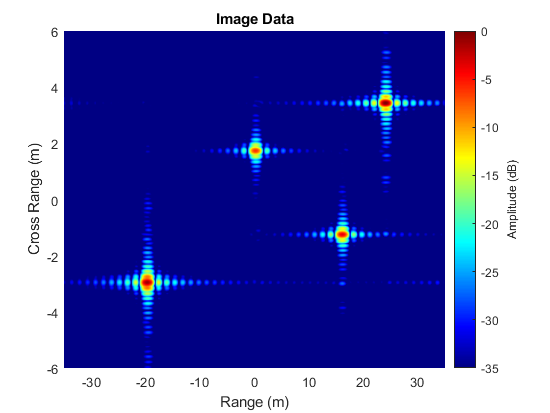


% Set the window type for azimuth compression
window = 'none';

% Get the window coefficients
switch window
    case 'Hanning'
        coefficients = hanning(nAz);
    case 'Hamming'
        coefficients = hamming(nAz);
    case 'Kaiser'
        coefficients = kaiser(nAz, 6);
    otherwise
        coefficients = ones(1, nAz);
end

% Set up the image array
range_doppler_image = zeros(nfft_Az, nfft_Range);

% Loop over the range lines and perform azimuth compression
for ir = 1:nfft_Range
    a = coefficients.*exp(-1j * 4 * pi * center_frequency / c * synthetic_aperture.^2 / (range_center(round(end/2)) + slant_range(ir)));
    af = fft(a, nfft_Az);
    range_doppler_image(:, ir) = ifftshift( ifft( fft(rd_data_corrected(:, ir), nfft_Az).*af') );
end

% Set up the cross range array
cross_range = linspace(-0.5 * aperture_length * nAz / nfft_Az, 0.5 * aperture_length * nAz / nfft_Az, nfft_Az);

% Plot the final range Doppler image
figure; pcolor(slant_range, cross_range, 20*log10( abs(range_doppler_image)./max(max(abs(range_doppler_image)))) ); shading flat
h = colorbar;
ylabel(h, 'Amplitude (dB)')
xlabel('Range (m)')
ylabel('Cross Range (m)');
title('Image Data');
ylim([-6, 6])
caxis([-35, 0])
colormap 'jet'